clear;
x1 = load('IrisData/class_1','-ascii'); % Iris-setosa 50x4
x2 = load('IrisData/class_2','-ascii'); % Iris-versicolor 50x4
x3 = load('IrisData/class_3','-ascii'); % Iris-virginica 50x4
dim_labels = {'Sepal Length (cm)', 'Sepal Width (cm)', 'Petal Length (cm)', 'Petal Width (cm)'};
class_labels = {'Iris-setosa', 'Iris-versicolor', 'Iris-virginica'};

%% Endre på disse for å endre hvilke sampler som blir brukt til trening og testing
x1_train = x1(1:30,:); 
x1_test = x1(31:50,:);
x2_train = x2(1:30,:);
x2_test = x2(31:50,:);
x3_train = x3(1:30,:);
x3_test = x3(31:50,:);
%%

X_train = [x1_train; x2_train; x3_train];
Y_train = [ones(size(x1_train, 1), 1); ...
           2 * ones(size(x2_train, 1), 1); ...
           3 * ones(size(x3_train, 1), 1)];

X_test = [x1_test; x2_test; x3_test];
Y_test_true = [ones(size(x1_test, 1), 1); ...
               2 * ones(size(x2_test, 1), 1); ...
               3 * ones(size(x3_test, 1), 1)];


% Opptrening
X = [X_train ones(size(X_train, 1), 1)]';

iterations = 3000;
alphas = [1/99 1/100 1/101]; % Forskjellige steglengder

mses = zeros(length(alphas), iterations);
t_k=[1 0 0; 0 1 0; 0 0 1];
W=cell(1,length(alphas)); % Cell nr1 tilhører alphas(1) osv

for a = 1:length(alphas)
    W_temp = zeros(length(class_labels), length(dim_labels) + 1);
    for it = 1:iterations
        gradMSE = 0;
        mseIt=0;
        z_k=W_temp*X;
        g_k=sigmoid(W_temp*X);
        for i=1:size(g_k,2)
            gradMSE = gradMSE + (g_k(:,i) - t_k(:,Y_train(i))) .* g_k(:,i) .* (ones(size(g_k(:,i))) - g_k(:,i))*X(:,i)';
            mseIt = mseIt + (g_k(:,i) - t_k(:,Y_train(i)))'*(g_k(:,i) - t_k(:,Y_train(i)));
        end
        mses(a,it)=mseIt/2;
        W_temp=W_temp-alphas(a)*gradMSE;
    end
    W{a}=W_temp;
end

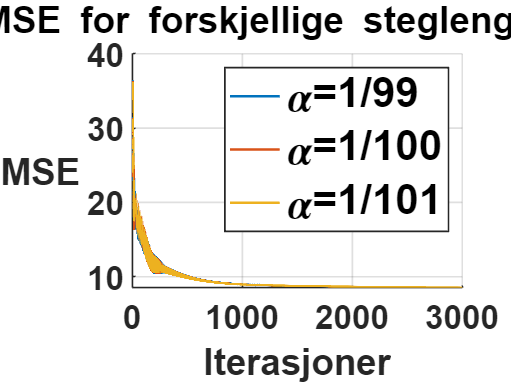

% Plot MSE
figure;
hold on;
grid on;
for a = 1:length(alphas)
    [n, d] = rat(alphas(a));
    plot(1:iterations, mses(a,:),'LineWidth',1.5,'DisplayName',['\alpha=',num2str(n),'/',num2str(d)]);
end
xlabel('Iterasjoner');
ylabel('MSE');
title('MSE for forskjellige steglengder \alpha');
lgd = legend();
lgd.FontSize = 25;
ax = gca;
ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';
set(get(gca,'YLabel'),'Rotation',0)
hold off;

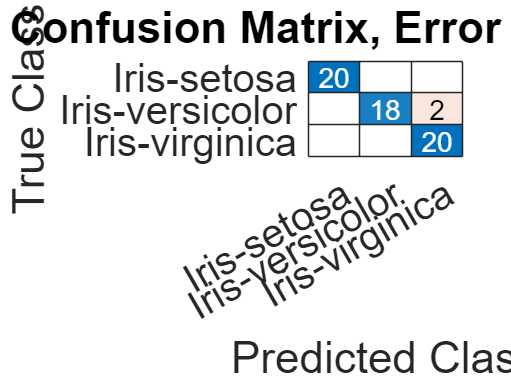


% Test 
X_test_augmented = [X_test ones(size(X_test, 1), 1)]';
g_test = W{3} * X_test_augmented;
[~, Y_test_pred] = max(g_test);

confusion_matrix = confusionmat(Y_test_true, Y_test_pred);
error_rate = 1 - sum(diag(confusion_matrix)) / sum(confusion_matrix(:));

figure;
confusionchart(confusion_matrix, class_labels,'FontSize',24);
title(['Confusion Matrix, Error Rate: ', num2str(round(error_rate * 100,2)), '%']);


disp(num2str(W{1},4));

0.4507      1.785     -2.651     -1.231     0.3206
 1.475      -3.07    -0.2692     -1.036       2.16
 -3.27     -2.817      4.799      4.346     -2.338
